# 4D 图：slice 切片显示

- [Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

- [Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

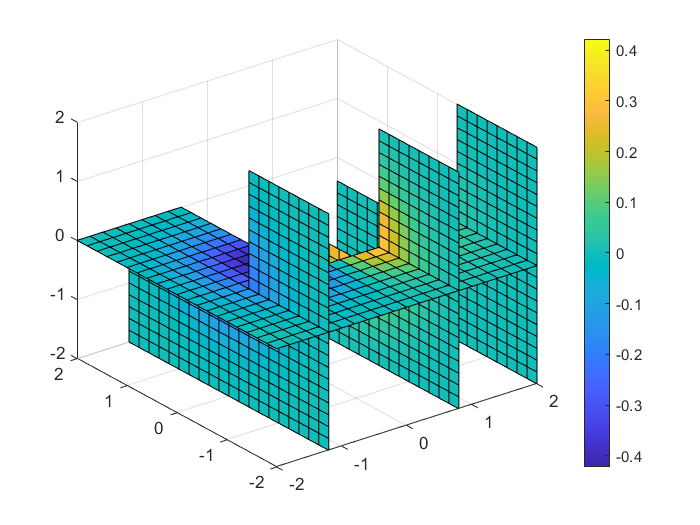

clear;clc;
[X, Y, Z] = meshgrid(-2:0.2:2);
V = X .* exp(-X.^2 - Y.^2 - Z.^2);
% 切片位置
xslice = [-1.2, 0.8, 2];   
yslice = [];
zslice = 0;
s = slice(X, Y, Z, V, xslice, yslice, zslice);
for i = 1:length(s)
    s(i).XData(10:end, 10:end) = nan;
    s(i).YData(10:end, 10:end) = nan;
    s(i).ZData(10:end, 10:end) = nan;
end
% 加 colorbar 方便看值
colorbar